# ECEN 5463 HW 4

Collin Thornton

## Problem 1

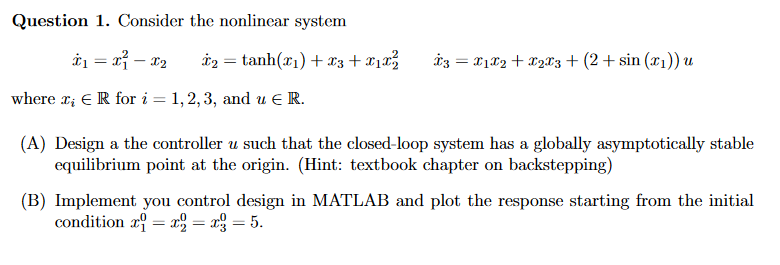

## 1-1 Design a controller $u$ **such that the closed-loop system has a globally asymptotically stable equilibrium point at the origin**

We follow the recursive application as outlined in the book.


$$\dot{x} =f_0 \left(x\right)+g_0 \left(x\right)z_1$$



$$\dot{z_1 } =f_1 \left(x,z_1 \right)+g_1 \left(x,z_1 \right)z_2$$



$$\dot{z_2 } =f_2 \left(x,z_1 ,z_1 \right)+g_2 \left(x,z_1 ,z_2 \right)z_3$$


where the following relations hold:


$$z_3 =u$$



$$f_0 \left(x\right)=x^2$$
        
$$g_0 \left(x\right)=-1$$



$$f_1 \left(x,z_1 \right)=\tanh \left(x\right)+{\mathrm{xz}}_1^2$$
    
$$g_2 \left(x,z_1 \right)=1$$


 
$$f_2 \left(x,z_1 ,z_2 \right)={\mathrm{xz}}_1 +z_1 z_2$$
    
$$g_2 \left(x,z_1 ,z_2 \right)=2+\sin \left(x\right)$$


Define $V_0 \left(x\right)=\frac{1}{2}x^2$   and $\phi_0 \left(x\right)=x^2 +x$ such that $\dot{V_0 }$ is negative definite.

Now let $\phi_1 \left(x,z_1 \right)=\frac{\partial \phi_0 }{\partial x}\left(f_0 +g_0 z_1 \right)-\frac{\partial V_0 }{\partial x}g_0 -k_1 \left(z_1 -\phi_0 \right)-f_1$ for some $k_1 >0$

Expanding, $\phi_1 \left(x,z_1 \right)=\left(2x+1\right)\left(x^2 -z_1 \right)+x-k_1 \left(z_1 -x^2 -x\right)-\tanh \left(x\right)+{\mathrm{xz}}_1^2$


$$\phi_1 \left(x,z_1 \right)=2x^3 -2{\mathrm{xz}}_1 +x^2 -z_1 +x-k_1 z_1 +k_1 x^2 +k_1 x-\tanh \left(x\right)+{\mathrm{xz}}_1^2$$


Now let $\phi_2 \left(x,z_1 ,z_2 \right)=-\frac{\partial \phi_1 }{\partial x}\left(f_0 +g_0 z_1 \right)-\frac{\partial \phi_1 }{\partial z_1 }\left(f_1 +g_1 z_2 \right)+\frac{\partial V_1 }{\partial z_1 }g_1 +k_2 \left(z_2 -\phi_1 \right)+f_2$ for some $k_2 >0$

and let $V_2 \left(x,z_1 ,z_2 \right)=V_1 \left(x,z_1 \right)+\frac{1}{2}{\left(z_2 -\phi_2 \left(x,z_1 \right)\right)}^2$

As this is a third order system, $\phi_2 =u$. Proving GAS requires that each candidation function $V_{0\ldotp \ldotp 2}$ be positive definite and radially unbounded, which they are. We also need $\dot{V_{0\ldotp \ldotp \ldotp 2} }$ to be negative definite. As $\dot{V_0 }$ is negative definite, picking an arbitrarily large $k_1 ,k_2 >0$ will force $V_1$ and $V_2$ to be negative definite as well. 

clear all;

syms x
syms z [3 1]

f = [x^2-z1;
     tanh(x)+z2+x*z1^2;
     x*z1+z1*z2+(2+sin(x))*z3]

$$f = \left(\begin{array}{c} x^{2}-z_{1}\\ x\,{z_{1}}^{2}+z_{2}+\tanh\left(x\right)\\ z_{3}\,\left(\sin\left(x\right)+2\right)+x\,z_{1}+z_{1}\,z_{2} \end{array}\right)$$

f0 = x^2;
g0 = -1;

f1 = tanh(x)+x*z1^2;
g1 = 1;

f2 = x*z1+z1*z2;
g2 = (2+sin(x));

V0 = 1/2*x^2;
phi0 = x^2+0.1*x;

k1 = 800;
phi1 = 1/g1 * (diff(phi0,x)*(f0+g0*z1) - diff(V0,x)*g0 -k1*(z1-phi0) - f1);

k2 = 1000;
V1 = V0 + 1/2*(z1-phi0)^2;
phi2 = 1/g2 * (diff(phi1,x)*(f0+g0*z1) + diff(phi1,z1)*(f1+g1*z2) - diff(V1,z1)*g1 - k2*(z2-phi1) - f2);
V2 = V1 + 1/2*(z2-phi2)^2;

dV0 = diff(V0,x)*(f0+g0*phi0)

$$dV0 = -\frac{x^{2}}{10}$$

### 1-2 Simulate to show that the controller works at the initial condition $x_1^0 =x_2^0 =x_3^0 =5$

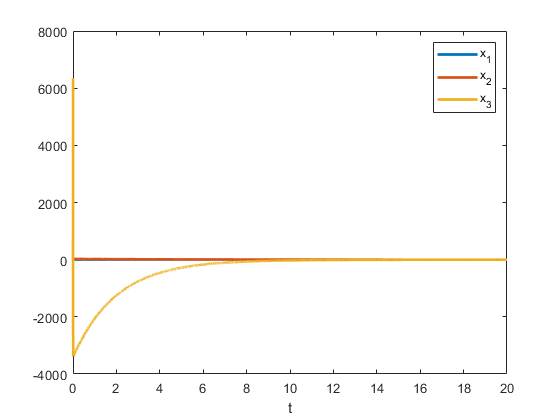

F = matlabFunction(f,"Vars", {[x;z1;z2],z3}, "File", "F");
cntrl = matlabFunction(phi2, "Vars", {[x;z1;z2]});
[t,y] = ode45(@(t,x) F(x,cntrl(x)), [0 20], [5;5;5]);
plot(t,y, "LineWidth", 2)
xlabel("t")
legend("x_1", "x_2", "x_3")